% 目的：Flexural wave propagation in beams with periodically attached vibration absorbers: Band-gap behavior and band formation mechanisms
% Figure 6
% 
% 状态：
% ================================================

## 参数设置

clear;clc


%% 1. 几何参数 (Table 1)
geometry.h = 0.015;      % 梁高度 [m]
geometry.l = 0.01;       % 间距 [m]
geometry.r1 = 0.013;     % 内半径 [m]
geometry.r2 = 0.015;     % 中间半径 [m]
geometry.r3 = 0.018;     % 外半径 [m]
geometry.L = 0.1;        % 梁总长度 [m]

%% 2. 材料参数 (Table 2)
% 铝层参数
material.aluminum.E = 7e10;          % 杨氏模量 [Pa]
material.aluminum.G = 2.7e10;        % 剪切模量 [Pa]
material.aluminum.rho = 2700;        % 密度 [kg/m^3]

% 橡胶层参数
material.rubber.E = 7.748e5;         % 杨氏模量 [Pa]
material.rubber.G = 2.6e5;           % 剪切模量 [Pa]
material.rubber.rho = 1300;          % 密度 [kg/m^3]

% 铜层参数
material.copper.E = 1.65e11;         % 杨氏模量 [Pa]
material.copper.G = 7.53e10;         % 剪切模量 [Pa]
material.copper.rho = 8700;          % 密度 [kg/m^3]

%% 3. 截面特性计算
% 梁的横截面积
geometry.A = pi*(geometry.r3^2-geometry.r2^2);
% 梁的惯性矩
geometry.I = pi*(geometry.r3^4-geometry.r2^4)/4;

%% 4. DVA参数计算
% 形状参数 S = l / [(r1 + r2) * ln(r2/r1)]
geometry.DVA.S = geometry.l / ((geometry.r1 + geometry.r2) * log(geometry.r2/geometry.r1));

% DVA质量 m = ρ_Cu * π * （r3²-r2²） * h
material.DVA.m = material.copper.rho * pi * (geometry.r1^2) * geometry.h;

% DVA弹簧刚度 k = [π(5 + 3.29S²)Gl] / ln(r₂/r₁)
material.DVA.k = (pi * (5 + 3.29*geometry.DVA.S^2) * material.rubber.G * geometry.l) / ...
             log(geometry.r2/geometry.r1);

f_b1 = calculate_fundamental_frequency(material, geometry)

f_b1 = 9.3701e+03

f_R = calculate_resonant_frequency(material)

f_R = 729.3626

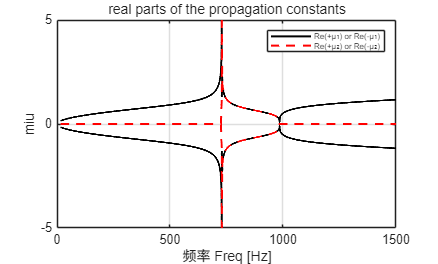


% 频率扫描参数设置
omega_values = linspace(100, 10000, 10000);  % 频率范围 [rad/s]
fre_values = omega_values ./ (2*pi());          % 转换为Hz

% 预分配存储空间
mu_results = zeros(length(omega_values), 4);  % 存储F1和F2

for i = 1:length(omega_values)
    omega = omega_values(i);

    % 计算各参数
    D_0 = calculate_DVA_stiffness(omega, material);
    % D_beam = spectral_element_matrix(omega, material, geometry);
    
    [mu, ~] = calculate_mu(material, geometry, D_0, omega);

    % 存储结果（取实部）
    mu_results(i, :) = [real(mu(1)), imag(mu(1)), ...
                             real(mu(2)), imag(mu(2))];

    % % 显示进度
    % if mod(i,10) == 0
    %     fprintf('已完成 %.1f%%, 当前频率 %.2f Hz\n', i/length(omega_values)*100, omega ./ (2*pi()));
    % end
end

%% 复现Figure 3a
figure;
% 绘制μ1和μ2的实部
% subplot(4,1,1);
p1 = plot(fre_values, mu_results(:,1), 'black-', 'LineWidth', 1.5); hold on;  % F1实部
     plot(fre_values, -mu_results(:,1), 'black-', 'LineWidth', 1.5);          % F1实部
p2 = plot(fre_values, mu_results(:,3), 'r--', 'LineWidth', 1.5);
     plot(fre_values, -mu_results(:,3), 'r--', 'LineWidth', 1.5);
xlabel('频率 Freq [Hz]');
ylabel('miu');
legend([p1 p2], {'Re(+μ₁) or Re(-μ₁)', 'Re(+μ₂) or Re(-μ₂)'}, ...
       'Location', 'northeast', 'FontSize', 6);
title('real parts of the propagation constants');
grid on;
xlim([0 1500]);
ylim([-5 5]);

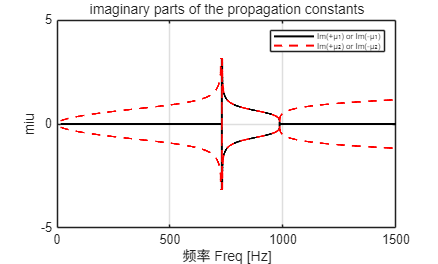


%% 复现Figure 3b
figure;
% 绘制μ1和μ2的虚部
p1 = plot(fre_values, mu_results(:,2), 'black-', 'LineWidth', 1.5); hold on;  % F1实部
     plot(fre_values, -mu_results(:,2), 'black-', 'LineWidth', 1.5);          % F1实部
p2 = plot(fre_values, mu_results(:,4), 'r--', 'LineWidth', 1.5);
     plot(fre_values, -mu_results(:,4), 'r--', 'LineWidth', 1.5);
xlabel('频率 Freq [Hz]');
ylabel('miu');
legend([p1 p2], {'Im(+μ₁) or Im(-μ₁)', 'Im(+μ₂) or Im(-μ₂)'}, ...
       'Location', 'northeast', 'FontSize', 6);
title('imaginary parts of the propagation constants');
grid on;
xlim([0 1500]);
ylim([-5 5]);

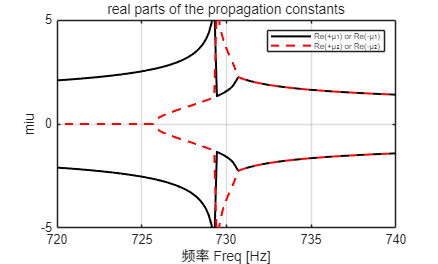


%% 复现Figure 3c
figure;
% 绘制μ1和μ2的实部局部放大
% subplot(4,1,1);
p1 = plot(fre_values, mu_results(:,1), 'black-', 'LineWidth', 1.5); hold on;  % F1实部
     plot(fre_values, -mu_results(:,1), 'black-', 'LineWidth', 1.5);          % F1实部
p2 = plot(fre_values, mu_results(:,3), 'r--', 'LineWidth', 1.5);
     plot(fre_values, -mu_results(:,3), 'r--', 'LineWidth', 1.5);
xlabel('频率 Freq [Hz]');
ylabel('miu');
legend([p1 p2], {'Re(+μ₁) or Re(-μ₁)', 'Re(+μ₂) or Re(-μ₂)'}, ...
       'Location', 'northeast', 'FontSize', 6);
title('real parts of the propagation constants');
grid on;
xlim([720 740]);
ylim([-5 5]);

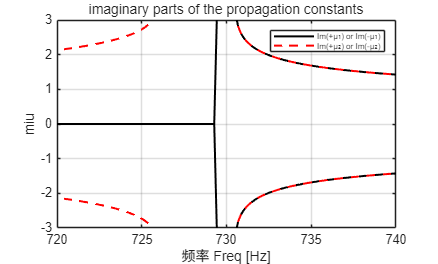


%% 复现Figure 3d
figure;
% 绘制μ1和μ2的虚部局部放大
p1 = plot(fre_values, mu_results(:,2), 'black-', 'LineWidth', 1.5); hold on;  % F1实部
     plot(fre_values, -mu_results(:,2), 'black-', 'LineWidth', 1.5);          % F1实部
p2 = plot(fre_values, abs(mu_results(:,4)), 'r--', 'LineWidth', 1.5);
     plot(fre_values, -abs(mu_results(:,4)), 'r--', 'LineWidth', 1.5);
xlabel('频率 Freq [Hz]');
ylabel('miu');
legend([p1 p2], {'Im(+μ₁) or Im(-μ₁)', 'Im(+μ₂) or Im(-μ₂)'}, ...
       'Location', 'northeast', 'FontSize', 6);
title('imaginary parts of the propagation constants');
grid on;
xlim([720 740]);
ylim([-3 3]);

function kb = calculate_wave_number(omega, material, geometry)
    % 计算波数kb
    % 输入参数：
    %   omega : 角频率 [rad/s]
    %   material : 材料参数结构体
    %   geometry : 几何参数结构体
    %
    % 输出参数：
    %   kb : 波数 [rad/m]
    
    kb = (material.aluminum.rho * geometry.A * omega^2 / ...
         (material.aluminum.E * geometry.I))^(1/4);
end

% 梁谱元矩阵 %
function D_beam = spectral_element_matrix(omega, material, geometry)
    % 输入参数：
    %   omega : 角频率 [rad/s]
    %   material : 材料参数结构体
    %   geometry : 几何参数结构体
    %
    % 输出参数：
    %   D_beam : 4×4梁刚度矩阵
    
    % 统一调用kb计算函数
    kb = calculate_wave_number(omega, material, geometry);
    kbL = kb * geometry.L;

    % 计算分母Δ
    Delta = 1 - cos(kbL)*cosh(kbL);

    % 计算各系数
    alpha = (cos(kbL)*sinh(kbL) + sin(kbL)*cosh(kbL)) * (kbL)^3 / Delta;
    alpha_bar = (sin(kbL) + sinh(kbL)) * (kbL)^3 / Delta;
    beta = (-cos(kbL)*sinh(kbL) + sin(kbL)*cosh(kbL)) * kbL / Delta;
    beta_bar = (-sin(kbL) + sinh(kbL)) * kbL / Delta;
    gamma = (-cos(kbL) + cosh(kbL)) * (kbL)^2 / Delta;
    gamma_bar = sin(kbL)*sinh(kbL) * (kbL)^2 / Delta;

    % 构建刚度矩阵
    EI = material.aluminum.E * geometry.I;  % 弯曲刚度
    L = geometry.L;                         % 梁长度

    D11 = (EI/L^3) * [alpha, gamma_bar*L; gamma_bar*L, beta*L^2];
    D12 = (EI/L^3) * [-alpha_bar, gamma*L; -gamma*L, beta_bar*L^2];
    D21 = D12';  % D21是D12的转置
    D22 = (EI/L^3) * [alpha, -gamma_bar*L; -gamma_bar*L, beta*L^2];

    D_beam = [D11, D12; D21, D22];
end

function D_0 = calculate_DVA_stiffness(omega, material)
    % 输入参数：
    %   omega : 频率
    %   geometry : 包含材料参数的结构体
    %
    % 输出参数：
    %   D_0 : DVA动刚度

    % 读取参数
    k = material.DVA.k;
    m = material.DVA.m;

    % 计算：
    D_0 = k - k^2 / (k - omega^2 * m);
end

function f_b1 = calculate_fundamental_frequency(material, geometry)
    % 输入参数：
    %   material : 包含材料参数的结构体
    %   geometry : 包含几何参数的结构体
    %
    % 输出参数：
    %   f_b1 : 一阶弯曲固有频率 [Hz]
    
    % 读取参数
    L = geometry.L;               % 梁总长度 [m]
    E = material.aluminum.E;      % 铝杨氏模量 [Pa]
    I = geometry.I;               % 惯性矩 [m^4]
    rho = material.aluminum.rho;  % 铝密度 [kg/m^3]
    A = geometry.A;               % 横截面积 [m^2]

    % 计算：
    f_b1 = (1/(2*pi)) * (pi/L)^2 * sqrt((E*I)/(rho*A));
end

function f_R = calculate_resonant_frequency(material)
    % 计算系统共振频率 (基于图片公式 e_fR = (1/2π)√(k/m))
    % 输入参数：
    %   material : 包含材料参数的结构体
    %   geometry : 包含几何参数的结构体
    %
    % 输出参数：
    %   f_R : 系统共振频率 [Hz]
    
    % 读取参数
    k = material.DVA.k;       % 弹簧刚度 [N/m]
    m = material.DVA.m;              % 质量 [kg] (铜柱质量)
    
    % 计算
    f_R = (1/(2*pi)) * sqrt(k/m);
end

function [mu, cosh_mu] = calculate_mu(material, geometry, D0, omega)
    % 计算振动特征方程的根并求解μ值
    % 输入参数：
    %   material : 包含材料参数的结构体
    %   geometry : 包含几何参数的结构体
    %   D0 : 动态刚度 [N/m]
    %   omega : 频率
    %
    % 输出参数：
    %   mu : 特征方程的根 [μ1, μ2]
    %   cosh_mu : 双曲余弦根 [F1, F2]
    %   alpha1 : 中间参数α₁
    %   alpha2 : 中间参数α₂

    % 统一调用kb计算函数
    kb = calculate_wave_number(omega, material, geometry);

    % 从结构体读取参数
    L = geometry.L;               % 梁长度 [m]
    E = material.aluminum.E;      % 杨氏模量 [Pa]
    I = geometry.I;               % 惯性矩 [m^4]
    kbL = kb * L;   
  
    % 计算α₁ (图片第二个公式)
    term1_alpha1 = -(cos(kbL) + cosh(kbL));
    term2_alpha1 = -(D0/(4*E*I*kb^3)) * (sin(kbL) - sinh(kbL));
    alpha1 = term1_alpha1 + term2_alpha1;
    
    % 计算α₂ (图片第三个公式)
    term1_alpha2 = cos(kbL) * cosh(kbL);
    term2_alpha2 = (D0/(4*E*I*kb^3)) * ...
                  (sin(kbL)*cosh(kbL) - sinh(kbL)*cos(kbL));
    alpha2 = term1_alpha2 + term2_alpha2;
    
    % 计算双曲余弦根 (图片第一个公式)
    discriminant = alpha1^2 - 4*alpha2;
    if discriminant < 0
        % 复数根处理
        sqrt_discriminant = sqrt(complex(discriminant)); % 强制复数运算
        cosh_mu = [(-alpha1 + sqrt_discriminant)/2,  % F1
                   (-alpha1 - sqrt_discriminant)/2]; % F2
        % disp('警告：判别式为负，返回复数解');
    else
        % 实数根处理
        cosh_mu = [(-alpha1 + sqrt(discriminant))/2,  % F1
                  (-alpha1 - sqrt(discriminant))/2];  % F2
    end

    % 从cosh(μ)求解μ
    mu = zeros(size(cosh_mu));
    for i = 1:numel(cosh_mu)
        cm = cosh_mu(i);
        if isreal(cm)
            if cm >= 1
                mu(i) = acosh(cm);
            else
                mu(i) = 1i * acos(cm);
            end
        else
            mu(i) = acosh(cm);
        end
    end
    mu = reshape(mu, size(cosh_mu));
end
